opt.max_rate = 0.25/10;
opt.track_len = 120; %cm
opt.field_std = 3; %cm
opt.max_v = 30; %cm/s
opt.noise_sigma = 0;%10; %cm
opt.session_time = hours(0.5); %duration
opt.dt = seconds(1/20); %duration


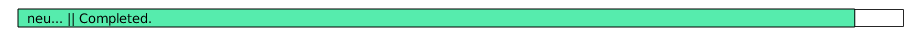

t_ = tic;

total_n_cells = 500;
d_neu = 30;
ns = unique([1, d_neu:d_neu:total_n_cells, total_n_cells]);

%progressbar('reps...', 'neu...');
progressbar('neu...');
n_reps = 80;

[mse_short, mse_sh_short] = deal(zeros(n_reps, numel(ns)));

for n_ix = numel(ns):-1:1
parfor r_ix = 1:n_reps
    
        [mse_short(r_ix, n_ix), mse_sh_short(r_ix, n_ix)] = decoding_simulator(ns(n_ix), opt);
        %progressbar([], n_ix / numel(ns));
    
    %progressbar(r_ix/n_reps);
    %fprintf('Done rep %d\n', r_ix);
end
progressbar((numel(ns) - n_ix + 1)/numel(ns));
end

toc(t_);

Elapsed time is 13507.081156 seconds.


t_ = tic;
opt.out_noise = 1.26e-1;
decoding_simulator(100, opt)

ans = 65.6123

toc(t_)

Elapsed time is 0.390743 seconds.


[fr_real_short, gof_real_short] = createFit_infoSaturation(ns, mean(1./mse_short))

fr_real_short =      General model:
     fr_real_short(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   3.561e-05  (2.41e-05, 4.712e-05)
       N =         210  (98.54, 321.5)

gof_real_short = struct with fields:
           sse: 3.1767e-06
       rsquare: 0.9421
           dfe: 16
    adjrsquare: 0.9385
          rmse: 4.4559e-04


[fr_shuf_short, gof_shuf_short] = createFit_infoSaturation(ns, mean(1./mse_sh_short))

fr_shuf_short =      General model:
     fr_shuf_short(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   3.613e-05  (2.391e-05, 4.834e-05)
       N =         210  (93.43, 326.6)

gof_shuf_short = struct with fields:
           sse: 3.5767e-06
       rsquare: 0.9381
           dfe: 16
    adjrsquare: 0.9342
          rmse: 4.7280e-04


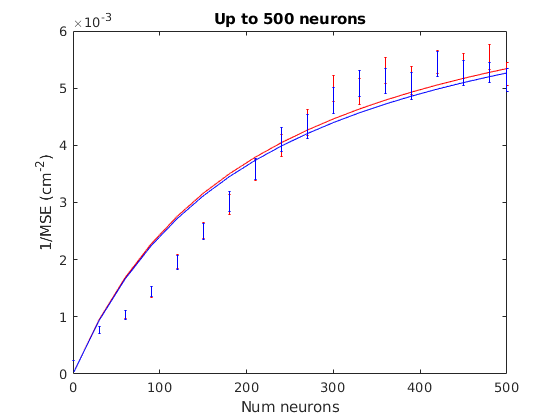


figure;
ep(ns, 1./mse_sh_short, 'r.'); hold on;
plot(ns, fr_shuf_short(ns), 'r');

ep(ns, 1./mse_short, 'b.');
plot(ns, fr_real_short(ns), 'b');
xlabel 'Num neurons'
ylabel '1/MSE (cm^{-2})'
title 'Up to 500 neurons'

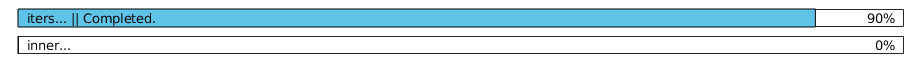

progressbar('iters...', 'inner...');
for i = 1:10
    pause(1);
    parfor j = 1:16
        pause(0.1);
        progressbar([], j/16);
    end
    progressbar(i/10);
end

function [mse, mse_sh] = decoding_simulator(num_neurons, opt)
g_field = @(x, m, s) opt.max_rate.*exp(-((x-m)./s).^2 ./ 2);

m = sort(rand(num_neurons, 1) * opt.track_len);

rate_func = @(x) g_field(single(x), single(m), single(opt.field_std));

response_sample = @(x) poissrnd(rate_func(x));
%response_sample = @(x) normrnd(rate_func(x), opt.out_noise);

t = seconds(seconds(0):opt.dt:opt.session_time);

x_traj = opt.track_len .* sin(opt.max_v./opt.track_len .* t).^2;

input_noise = opt.noise_sigma*randn(size(x_traj));

X_noise = response_sample(x_traj + input_noise);

dt_opts = DecodeTensor.default_opt;
[~,~,tr_s,tr_e,tr_dir,tr_bins,~] = DecodeTensor.new_sel([x_traj(:), 0*x_traj(:)], dt_opts);
data_tensor = DecodeTensor.construct_tensor(X_noise.', tr_bins, dt_opts.n_bins, tr_s, tr_e);

alg = my_algs('ecoc');%fastpnb;
err_res = DecodeTensor.decode_all(data_tensor, tr_dir, opt.track_len/dt_opts.n_bins, alg, [], []);

mse = err_res.MSE.unshuffled;
mse_sh = err_res.MSE.shuffled;
end

function ep(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none", 'LineStyle', "none");
end